## Detector de automóviles en una autopista

% Conteo de autos 
% Carga imagen y recorta dos zonas: escena con autos, y solo pista
im = imread('cars.png');
image(im)
cars = im(51:271, 2:322, :);

RoadTrafficVideo1 =   VideoReader with properties:

   General Properties:
            Name: 'RoadTrafficVideo1.mp4'
            Path: 'E:\8vo ciclo\Procesamiento de Señales e Imágenes Digitales\Proyecto 2\Detector de automóviles en una autopista'
        Duration: 30.0634
     CurrentTime: 0
       NumFrames: <Calculating...> learn more

   Video Properties:
           Width: 256
          Height: 144
       FrameRate: 29.9700
    BitsPerPixel: 24
     VideoFormat: 'RGB24'



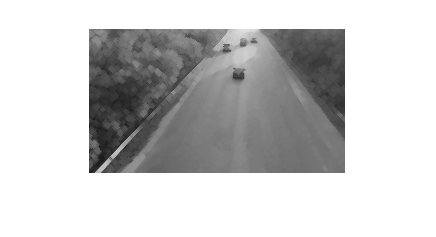

pista = im(51:271, 324:644, :);

figure, 
subplot(1, 2, 1), imshow(cars)
subplot(1, 2, 2), imshow(pista)

% Suma el absoluto de la diferencia de los 3 planos
dif = sum(abs(double(cars) - double(pista)), 3);
figure, imagesc(dif), colormap gray, axis image

% Histograma
h = imhist(uint8(dif), 256);
figure, plot(h), grid

% Umbralizamos para crear mascara de autos con valores sobre 120
mask1 = dif > 120;
figure, 
subplot(1, 2, 1), imshow(cars)
subplot(1, 2, 2), imshow(mask1)

% Filtrado pasabajos gaussiano
k = fspecial('gaussian', 5, 2);
%figure, surf(k)
bmf = filter2(k, mask1);
figure, imagesc(bmf), colormap gray, axis image

% Volvemos a umbralizar
bm2 = bmf > 0.75;
figure, imshow(bm2),


% Dilatamos con elemento estructural de 11x5 porque queremos fusionar 
% secciones de auto de manera vertical
se = ones(11, 5);
dil1 = imdilate(bm2, se);

% Closing para juntar mejor los autos
se2 = strel('disk', 2, 0)
autos1 = imclose(dil1, se2);

figure, 
subplot(1, 2, 1), imshow(dil1), title('Dilatacion inicial')
subplot(1, 2, 2), imshow(autos1), title('Closing')

% Etiquetamos cada objeto
L = bwlabel(autos1); 
figure, imagesc(L), axis image

% Obtiene coordenadas, boundingbox y excentricidad del centroide para cada objeto
info = regionprops(autos1, 'Centroid', 'BoundingBox', 'Eccentricity');

% Los objetos con alta excentricidad ( > 0.95) son alargados, como los bordes
n_blobs = max(L(:)); % Determinacion del numero de objetos

for ind = n_blobs:-1:1  % Para borrar desde el ultimo registro
  if info(ind).Eccentricity > 0.95
    info(ind) = []; % Elimina el registro
  end
end

n_cars = length(info);
% Dibuja boundingbox para cada auto
figure, imshow(cars), hold on,
for ind = 1:n_cars  
  rectangle('Position', info(ind).BoundingBox,'EdgeColor','r', 'LineWidth', 3)
end


clear all, close all;

RoadTrafficVideo1 = VideoReader('RoadTrafficVideo1.mp4')

obj = setupSystemObjects();

tracks = initializeTracks(); % Create an empty array of tracks.

nextId = 1; % ID of the next track

% Detect moving objects, and track them across video frames.
while hasFrame(obj.reader)
    frame = readFrame(obj.reader);
    [centroids, bboxes, mask] = detectObjects(frame);
    predictNewLocationsOfTracks();
    [assignments, unassignedTracks, unassignedDetections] = ...
        detectionToTrackAssignment();

    updateAssignedTracks();
    updateUnassignedTracks();
    deleteLostTracks();
    createNewTracks();

    displayTrackingResults();
end
% figure,pause(0.3);
% mask = rgb2gray(read(RoadTrafficVideo1,4));


% sedisk = strel('disk',2);
% noSmallStructures = imopen(RoadTrafficVideo1_gray, sedisk);
% imshow(noSmallStructures)

% nframes = RoadTrafficVideo1.NumFrames;
% I = read(RoadTrafficVideo1, 1);
% taggedCars = zeros([size(I,1) size(I,2) 3 nframes], class(I));


% for k = 1 : nframes
%     singleFrame = read(RoadTrafficVideo1, k);
%     
%     % Convert to grayscale to do morphological processing.
%     I = rgb2gray(singleFrame);
%     
%     % Remove dark cars.
%     noDarkCars = imextendedmax(I, darkCarValue); 
%     
%     % Remove lane markings and other non-disk shaped structures.
%     noSmallStructures = imopen(noDarkCars, sedisk);
% 
%     % Remove small structures.
%     noSmallStructures = bwareaopen(noSmallStructures, 150);
%    
%     % Get the area and centroid of each remaining object in the frame. The
%     % object with the largest area is the light-colored car.  Create a copy
%     % of the original frame and tag the car by changing the centroid pixel
%     % value to red.
%     taggedCars(:,:,:,k) = singleFrame;
%    
%     stats = regionprops(noSmallStructures, {'Centroid','Area'});
%     if ~isempty([stats.Area])
%         areaArray = [stats.Area];
%         [junk,idx] = max(areaArray);
%         c = stats(idx).Centroid;
%         c = floor(fliplr(c));
%         width = 2;
%         row = c(1)-width:c(1)+width;
%         col = c(2)-width:c(2)+width;
%         taggedCars(row,col,1,k) = 255;
%         taggedCars(row,col,2,k) = 0;
%         taggedCars(row,col,3,k) = 0;
%     end
% end
% 
% frameRate = RoadTrafficVideo1.FrameRate;
% implay(taggedCars,frameRate);